**Case 8: Lake Windermere Diatom Growth Model**

The diatom population of Lake Windermere has been observed to bloom in the spring and to disappear later in the season, presumably due to the consumption (uptake) of silica as the limiting nutrient.

Formulate a model to describe this phenomenon.

- Sketch the concentration of diatoms ($C_D$) and silica ($C_S$) predicted by the model vs. time.

- Plot the data from the table on the same graph.

**Preliminary Sketch**

**Solution**

First, I added time and given measurements of $C_D$ and $C_S$ into MATLAB. I decided to use mg/L as the units for $C_D \ldotp$

Input variables:

CSmeas = [2.17, 2.07, 1.90, 1.60, 1.20, 0.80, 0.50, 0.30, 0.22]; %mg/L
CDmeas = [0.0322, 0.0798, 0.210, 0.392, 0.595, 0.610, 0.504, 0.280, 0.035]; %mg/L
t = [0, 6, 12, 20, 26, 34, 41, 47, 60]; %days

Measured silica vs. diatom plot:

figure
plot(t,CSmeas,'o-')
hold on
plot(t,CDmeas, 'o-')
hold off
title(["Linear Plot of Silica vs. Diatom", "Concentration in Lake Windermere", "from 28 April to 28 June"])
ylabel("Concentration (mg/L)")
xlabel("time (d)")
legend("Silica", "Diatom")

....................................................................................................

For the model, I decided to use Michaelis-Menten kinetics to predict the change in silica and Monod kinetics to predict the change in diatom concentrations over 60 days. In the following equations, [M] is the diatom concentration (mg/L), [S] is the silica concentration (mg/L), $\mu_{\max }$ is the maximum growth rate, and $K_S$ is the Michaelis-Menten/Monod coefficient. $\gamma$ is the yield coefficient, which I left at 1 for this study.  

- $\frac{d\left\lbrack \textrm{Si}\right\rbrack }{t}=-\frac{\mu_{\max } \left\lbrack S\right\rbrack \left\lbrack M\right\rbrack }{K_S +\left\lbrack S\right\rbrack }$, change in silica concentration over time.

- $\frac{\textrm{dM}}{t}=\mu_{\max } \frac{\left\lbrack S\right\rbrack \left\lbrack M\right\rbrack }{K_S +\left\lbrack S\right\rbrack }\gamma -\left(K_L M\right)$, change in diatom concentration over time.

I first attempted to use the Runge-Kutta method to estimate the change in silica concentration over time, with $f\left(C_i ,t_i \right)=\frac{d\left\lbrack \textrm{Si}\right\rbrack }{t}$. I used the same time points as the measured data (time intervals = h) and I estimated $K_S$ as $0\ldotp 5\;d^{-1}$. I ended up varying $\mu_{\max }$ from 4 to 0.5 to get the curve to fit the measured silica concentrations as closely as possible. 


$$\begin{array}{l}
C_{i+1} =C_i +\frac{1}{6}\left(P+2q+2r+S\right)\\
P=\mathrm{hf}\left(C_i ,t_i \right)\\
q=\mathrm{hf}\left(C_i +\frac{P}{2},t_i +\frac{h}{2}\right)\\
r=\mathrm{hf}\left(C_i +\frac{q}{2},t_i +\frac{h}{2}\right)\\
S=\mathrm{hf}\left(C_i +r,t_i +h\right)
\end{array}$$


I then used the Runge-Kutta method to estimate change in diatom concentration over time followed by curve fitting to the measured data by varying the M-M coefficients. I kept $\mu_{\max }$ relatively constant at 0.4, except for the first and last time points, where I found that lowering it to around 0.1-0.15 caused the model to fit best. I kepth the loss coefficient ($K_L$) constant at 0.5 and I varied the substrate coefficient ($K_S$) from 0.1 to 0.5. I used the modeled silica concentration as the substrate concentration (S)  

- I did the calculations and curve fitting in Excel using my formulas from case 7. I input the modeled silica and diatom concentration data below.

CSmod = [2.17, 2, 1.97, 1.67, 1.20, 0.813, 0.528, 0.284, 0.130]; %mg/L
CDmod = [0.0322, 0.075, 0.232, 0.394, 0.586, 0.613, 0.499, 0.329, 0.041]; %mg/L

Lastly, I plotted the modeled and measured data on the same graph:

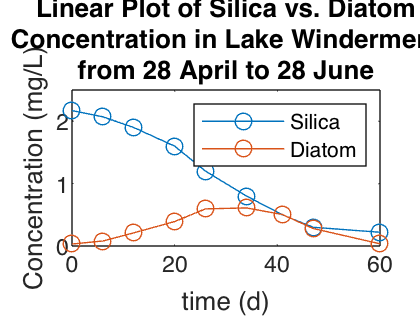

figure
plot(t,CSmeas,'o-')
hold on
plot(t,CDmeas, 'o-')
hold on
plot(t, CSmod, 'o-')
hold on
plot (t, CDmod, 'o-')
hold off
title(["Linear Plot of Silica vs. Diatom", "Concentration in Lake Windermere", "from 28 April to 28 June"])
ylabel("Concentration (mg/L)")
xlabel("time (d)")
legend("Measured Si", "Measured Diatom", "Modeled Si", "Modeled Diatom")